t = linspace(0,4*pi,50);
y1= sin(t);
y2=cos(t);

## 二维动画绘制

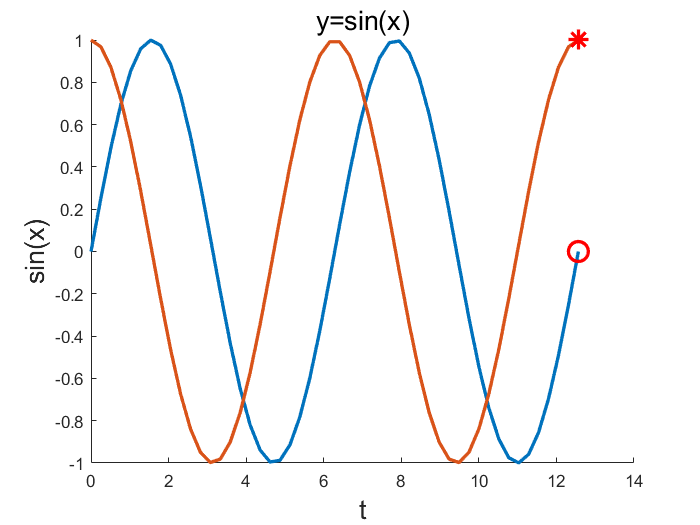

figure(1);clf;hold on;
xlabel('t',"FontSize",16);ylabel('sin(x)',"FontSize",16);
title('y=sin(x)',"FontSize",16);
plot(t,y1,'LineWidth',2);
plot(t,y2,'LineWidth',2);
for i = 1:length(t)
    if(i==1)
        circle1 = plot(t(i),y1(i),"ro","MarkerSize",12,"LineWidth",2);
        circle2 = plot(t(i),y2(i),"r*","MarkerSize",12,"LineWidth",2);
    else
        set(circle1,'xData',t(i),'yData',y1(i));
        set(circle2,'xData',t(i),'yData',y2(i));
    end
    pause(0.05);
    drawnow;
end


% comet(x,y)
% comet3(x,y,z)


## 创建保存 gif

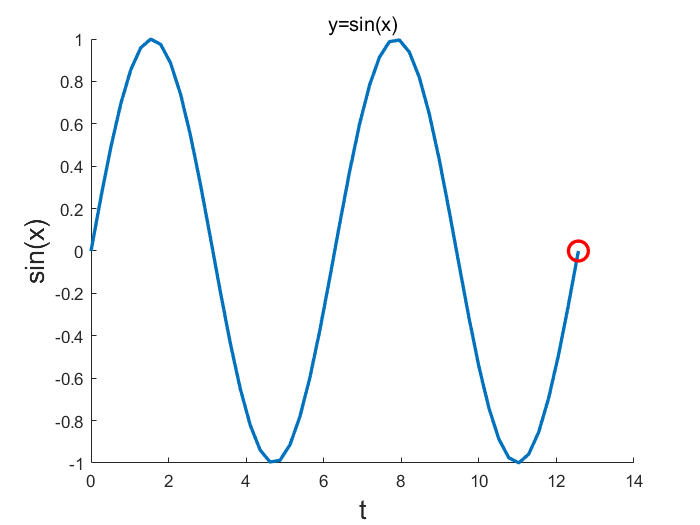

FigHanles = figure(1);clf;hold on;
xlabel('t',"FontSize",16);ylabel('sin(x)',"FontSize",16);
title('y=sin(x)',"FontSize",12);
% Set up GIF and log data
frameRate = 25;
fileName = '2D.gif'; % 文件名
frameDelay = 1/frameRate;
time = 0;

plot(t,y1,'LineWidth',2);
for i = 1:length(t)
    if(i==1)
        circle1 = plot(t(i),y1(i),"ro","MarkerSize",12,"LineWidth",2);
    else
        set(circle1,'xData',t(i),'yData',y1(i));
    end
    pause(0.05);
    drawnow; % Push the draw commands through the plot buffer
    
    % gif start
    im = frame2im(getframe(FigHanles));
    [imData, map] = rgb2ind(im, 256);
    % Write data
    if i==1  %First frame (create GIF file)
        imwrite(imData,map,fileName,'gif',...
            'LoopCount',inf,...
            'WriteMode','overwrite',...
            'DelayTime',frameDelay);
    else   %Append data to file
        imwrite(imData,map,fileName,'gif',...
            'WriteMode','append',...
            'DelayTime',frameDelay);
    end

    % time step system to next frame:
    time = time + frameDelay;
    % gif end
end

## 创建保存mp4/avi

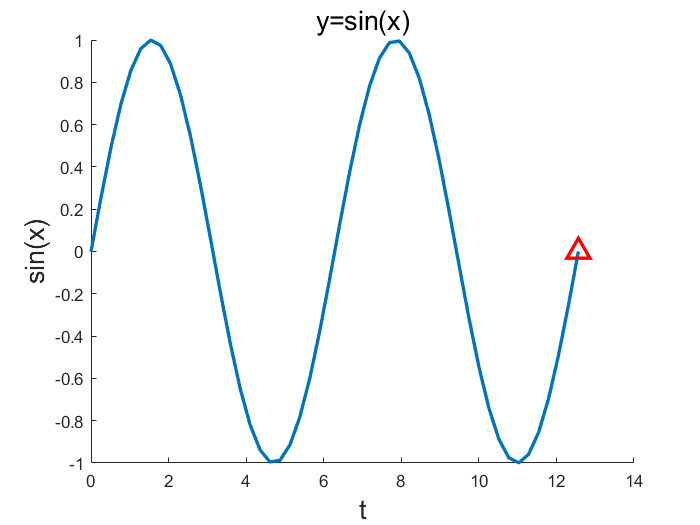

figure(1);clf;hold on;
filename='2D.mp4';
v = VideoWriter(filename);
open(v);


xlabel('t',"FontSize",16);ylabel('sin(x)',"FontSize",16);
title('y=sin(x)',"FontSize",16);
plot(t,y1,'LineWidth',2);
for i = 1:length(t)
    if(i==1)
        circle1 = plot(t(i),y1(i),"r^","MarkerSize",12,"LineWidth",2);
    else
        set(circle1,'xData',t(i),'yData',y1(i));
    end
    pause(0.05);
    drawnow;
    
    frame = getframe(gcf);
    writeVideo(v,frame);
end


close(v)
